# **ME2201 - TUTORIAL 8**

#### **AYUSH SINGH ME23B022 **

Made with MATLAB live script(.mlx)

### ANSWER 1:

For this problem we had to design a CAM in geogebra using the given data, the thing to notice here is that the question don't ask us to put any dwell in the design so it's just rise and return in a continous cycle.

The way we approach this problem is that we write the equations for boh rise and return with rise angle we divide them in 6 intervals of 30° each and find out how much the follower moves and mark there positions on the translation axis, and continue with the solution. For finding those points I am using MATLAB code which is shown below, i hae used cycloidal equation of motion.

%code for finding the rise and return points 
theta = 0:30:360;
thetar = theta*pi/(180);

for i = 1:1:6
    y(i) = 40*((theta(i))/180 - (1/(2*pi))*sin(2*pi*(theta(i))/180));
end

y(7) = 40;

for i = 8:1:13
    y(i) = 40*(1-((theta(i)-180)/180 - (1/(2*pi))*sin(2*pi*(theta(i)-180)/180)));
end

y;

This code give us both return and rise positions. Using them we can plot the cam profile, on geogebra we get something like this:

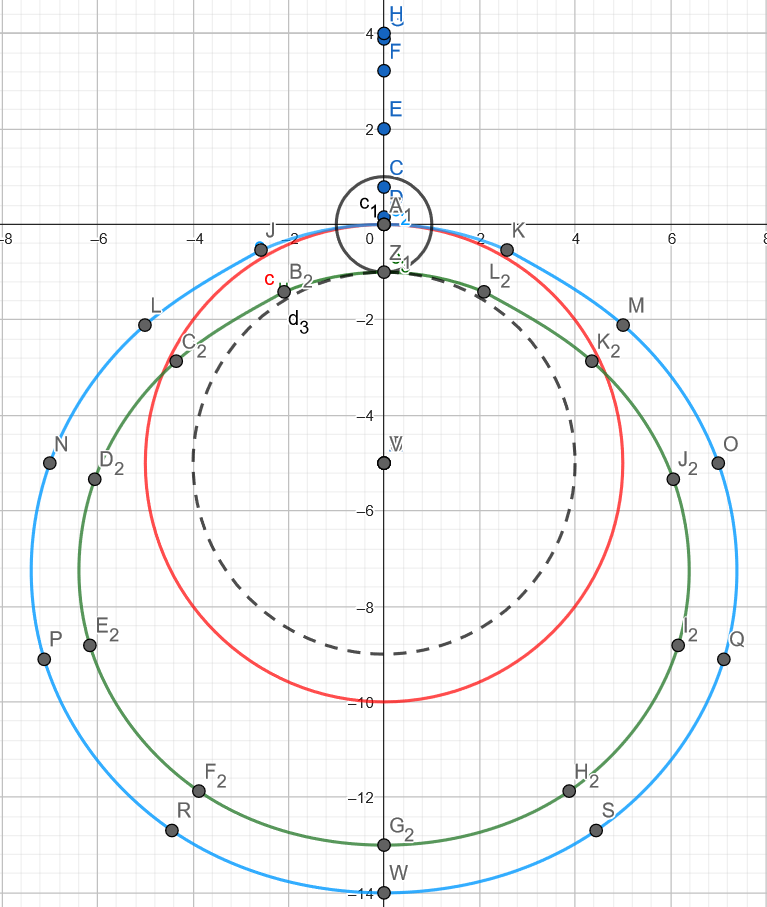

The graph for follower looks something like this:

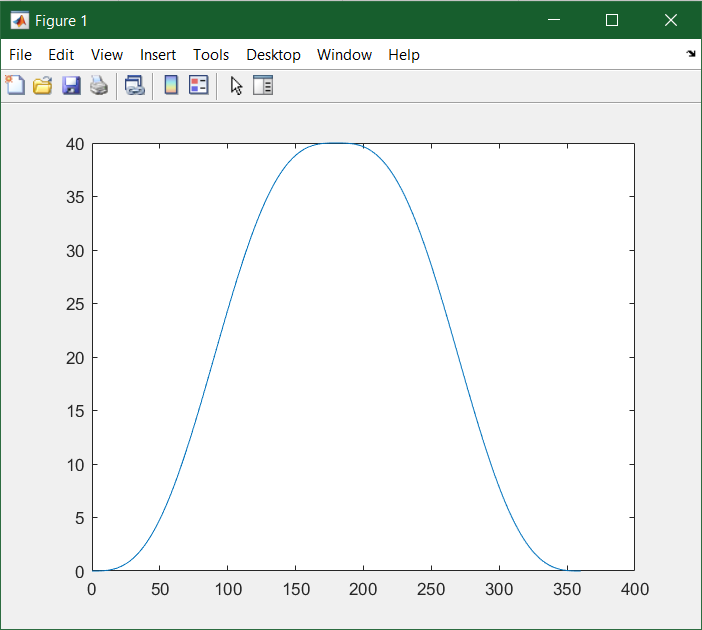

### **ANSWER 2:**

In this question we had to design the same CAM but analytically, apart from giving CAM profile my code can also give pressure angles. The second part of the question want to compare a different prime circle radii and there pressure angle variation they produced. 

Here's the code:

%code for finding the rise and return points 
theta = 0:1:360;%1 degree division for a more accurate profile
thetar = theta*pi/(180);%converting in radians

%for rise
for i = 1:1:180
    %the position of follower
    y(i) = 40*((theta(i))/180 - (1/(2*pi))*sin(2*pi*(theta(i))/180));
    %finding dy/dtheta
    w(i) = 40*(1/pi-(1/pi)*cos(2*pi*theta(i)/180));
    %finding pressure angles
    phi50(i) = atan(w(i)/(50+y(i)));%for prime circle 50mm
    phi70(i) = atan(w(i)/(70+y(i)));%for prime circle 70mm
end

y(181) = 40;
phi50(181) = 0;

%for return
for i = 182:1:361
    y(i) = 40*(1-((theta(i)-180)/180 - (1/(2*pi))*sin(2*pi*(theta(i)-180)/180)));
    w(i) = 40*(-1/pi + (1/pi)*cos(2*pi*(theta(i)-180)/180));
    phi50(i) = atan(w(i)/(50+y(i)));%for prime circle 50mm
    phi70(i) = atan(w(i)/(70+y(i)));%for prime circle 70mm
end

%cam profile while rise
for i = 1:1:180
    X(i) = (50+y(i))*sin(thetar(i));
    XC(i) = (-10*sin(phi50(i)))*cos(thetar(i)) + (50 + y(i) - 10*cos(phi50(i)))*sin(thetar(i));
    Y(i) = (50+y(i))*cos(thetar(i));
    YC(i) = (10*sin(phi50(i)))*sin(thetar(i)) + (50 + y(i) - 10*cos(phi50(i)))*cos(thetar(i));
end

X(181) = 0;
Y(181) = -90;
XC(181) = 0;
YC(181) = -80;

%cam profile while return
for i = 182:1:361
    X(i) = (50+y(i))*sin(thetar(i));
    XC(i) = (-10*sin(phi50(i)))*cos(thetar(i)) + (50 + y(i) - 10*cos(phi50(i)))*sin(thetar(i));
    Y(i) = (50+y(i))*cos(thetar(i));
    YC(i) = (10*sin(phi50(i)))*sin(thetar(i)) + (50 + y(i) - 10*cos(phi50(i)))*cos(thetar(i));
end
phid50 = phi50*180/pi;
phid70 = phi70*180/pi;

%plotting
subplot(1,2,1)
grid on
plot(XC,YC, 'b','LineWidth',2)
subplot(1,2,2)
grid on
plot(theta,phid50,'--',theta,phid70,'LineWidth',2)
xlabel('cam rotation')
ylabel('Pressure angle(phi)')
legend('50mm','70mm')

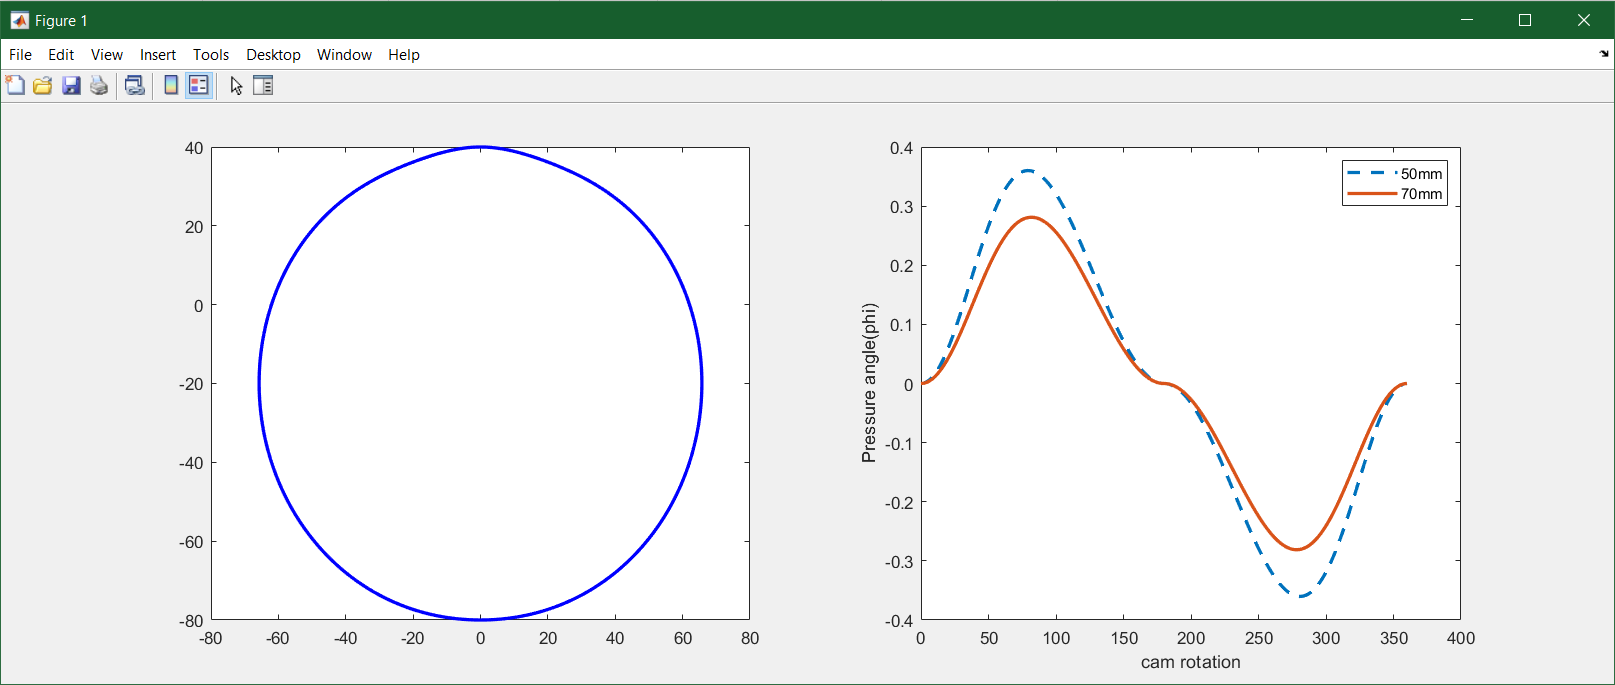

### **ANSWER 3**

The given question is on flat-face follower where we have been given the eccentricity (offet of translating axis from cam center). We have also been provided with angles of dwells, rise and return, and now we need to design this cam. The MATLAB code is given here. 

%code for flat face follower 
theta = 0:1:360;
thetar = theta*pi/180;

%for the initial dwell
for i = 1:1:90
    y(i) = 0;
    yy(i) = 0;
    XC(i) = 50*sin(thetar(i));
    YC(i) = 50*cos(thetar(i));
end

%for the rise
for i = 90:1:180
    y(i) = 25*((10*(theta(i)-90)^3/90^3)-15*((theta(i)-90)/90)^4+6*((theta(i)-90)/90)^5);
    yy(i)= 25*((10*3*(theta(i)-90)^2/90^3)-15*4*(((theta(i)-90))^3/90^4)+6*5*((theta(i)-90)^4/90^5));
    XC(i)= yy(i)*cos(thetar(i)) + (50+y(i))*sin(thetar(i));
    YC(i) = -yy(i)*sin(thetar(i)) + (50+y(i))*cos(thetar(i));
end

%for the second dwell
for i = 181:1:270
    y(i) = 25;
    yy(i) = 0;
    XC(i) = (50+y(i))*sin(thetar(i));
    YC(i) = (50+y(i))*cos(thetar(i));
end

%for the return
for i = 271:1:361
    y(i) = 25*(1-((10*(theta(i)-270)^3/90^3)-15*((theta(i)-270)/90)^4+6*((theta(i)-270)/90)^5));
    yy(i) = -25*3*((10*(theta(i)-270)^2/90^3)-15*3*((theta(i)-270)^3/90^4)+6*5*((theta(i)-270)^4/90^5));
    XC(i)= yy(i)*cos(thetar(i)) + (50+y(i))*sin(thetar(i));
    YC(i) = -yy(i)*sin(thetar(i)) + (50+y(i))*cos(thetar(i));
end

plot(XC,YC,'LineWidth',2)
grid on